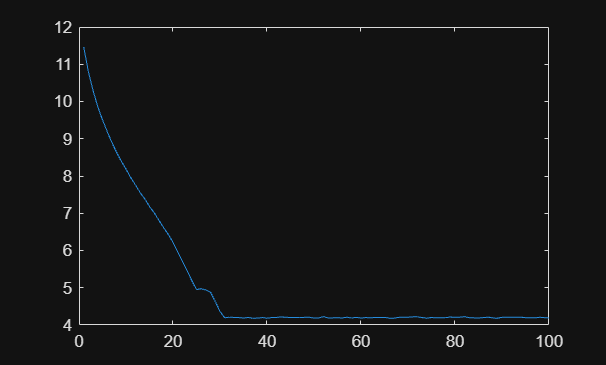

% genetic algorithm solution to find good sequences
startpoint = [0; 0]; % only consider one starting corner at a time

N = 100; % number of generations
P = 10000; % population size
w = .0001; % weight function to compare distance/turning
m = 0.05; % mutation rate

cities = [8.5, 6.2, 3.5, 5.1, 4.0, 0.8, 2.4, 1.2, 1.8, 2.4; 4.2, 0.5, 9.0, 9.4, 4.9, 4.9, 3.4, 9.0, 3.7, 1.1];
cityseq = perms(1:10);
sequences = [ones(length(cityseq), 1), cityseq; 2*ones(length(cityseq), 1), cityseq; 3*ones(length(cityseq), 1), cityseq; 4*ones(length(cityseq), 1), cityseq];
corners = [0, 10, 10, 0; 0, 0, 10, 10];
L = length(sequences);

% f = zeros(2, length(sequences));
% for i = 1:length(sequences)
%     f(:, i) = fscore(sequences(i, 2:11), startpoint, cities, W);
% end
% normalize f values
% f(1, :) = f(1, :)/max(f(1, :));
% f(2, :) = f(2, :)/max(f(2, :));

initialpop = ceil(rand(P, 1) * L);
initialseq = zeros(P, 10);
for i = 1:P
    initialseq(i, :) = sequences(initialpop(i), 2:11);
end
%figure(1)
%plotGen(initialseq, P, cities, startpoint)
op = initialseq;
scores = zeros(N, 1);
finalscores = zeros(P, 1);
for i = 1:N
    np = GAStep(op, 0.01, startpoint, cities, P, m);
    op = np;
    s = 0;
    for j = 1:P
        if i==N
            finalscores(j) = wfscore(np(j, :), startpoint, cities, w);
        end
        s = s + wfscore(np(j, :), startpoint, cities, w);
    end
    scores(i) = s/P; % average fitness score of population
end
figure(1)
plot(scores)

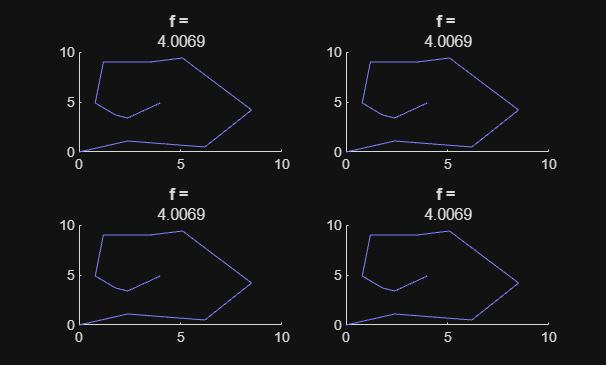

figure(2)
plotGen(np(1:4, :), 4, cities, startpoint, w)


function plotSeq(s, c, cities, startpoint)
    % s is an 1x10 vector of the city sequence
    % c is the color to be used, as a 1x3 row vector
    hold on;
    plot([startpoint(1), cities(1, s(1))], [startpoint(2), cities(2, s(1))], 'Color', c)
    for i = 1:9
        plot([cities(1, s(i)), cities(1, s(i+1))], [cities(2, s(i)), cities(2, s(i+1))], 'Color', c)
    end
end
function plotGen(sequences, P, cities, startpoint, w)
    % this stuff will make the subplot as close to square as possible for a
    % given population size
    l = floor(sqrt(P)); % length is the square root of population size, rounded down
    h = ceil(P/l); % height is sufficient to show all plots
    % sequences has P rows, each as a 1x10 row vector
    for i = 1:P
        subplot(h, l, i)
            plotSeq(sequences(i, :), [0.5, 0.5, 1], cities, startpoint)
            fs = fscore(sequences(i, :), startpoint, cities);
            title('f = ', num2str(fs(1) * w + fs(2))); % beware weight is hard coded
    end
end
function f = fscore(s, startpoint, cities)
    % calculate total distance:
    d2 = (startpoint(1)-cities(1, s(1)))^2 + (startpoint(2)-cities(2, s(1)))^2;
    for i = 1:9
        d2 = d2 + (cities(1, s(i))-cities(1, s(i+1)))^2 + (cities(2, s(i))-cities(2, s(i+1)))^2;
    end
    % calculate turning:
    v = zeros(2, 10); % preallocate
    v(:, 1) = cities(:, s(1)) - startpoint;
    csum = 0;
    for i = 1:9
        v(:, i+1) = cities(:, s(i+1)) - cities(:, s(i));
        csum = csum + 1 - dot(v(:, i), v(:, i+1))/(norm(v(:, i))*norm(v(:, i+1)));
    end
    % combined fitness score:
    f = [d2; csum];
end
function f = wfscore(s, startpoint, cities, w)
    f1 = fscore(s, startpoint, cities);
    f = f1(1) * w + f1(2);
end
function newpop = GAStep(curpop, w, startpoint, cities, P, mr)
    fpop = zeros(P, 1);
    for i = 1:P
        fs = fscore(curpop(i, :), startpoint, cities);
        fpop(i) = fs(1) * w + fs(2);
    end
    % sort rows based on fitness, best individuals at the top
    popranked = sortrows([fpop, curpop], 1, "ascend");
    % use only the top half as parents
    parents = popranked(1:floor(P/2), 2:11);
    % rerandomize the order of the parents
    prand = sortrows([rand(floor(P/2), 1), parents], 1, "ascend"); % sort by random column
    prand = prand(:, 2:11); % remove random column
    
    % preallocate children
    children = zeros(floor(P/2), 10);
    P2 = floor(P/2);
    for i = 1:floor(P2/2)
        children((2*i-1):(2*i), :) = splice(prand(2*i-1, :), prand(2*i, :));
    end
    % odd number of parents
    if(mod(P2, 2) == 1)
        c = splice(prand(P2, :), prand(P2-1, :));
        children(P2, :) = c(1, :);
    end
    npop = [parents; children]; % should have P rows
    % mutation step
    for i = 1:P
        k = rand();
        if (k < mr)
            idx = ceil(rand(2) * 10);
            buffer = npop(i, idx(1));
            npop(i, idx(1)) = npop(i, idx(2));
            npop(i, idx(2)) = buffer;
        end
    end
    newpop = npop;
end
function c = splice(s1, s2)
    idx = ceil(rand() * 9); % random num between 1 and 9 to splice at
    s11 = s1(1:idx);
    s12 = s1((idx+1):10);
    s21 = s2(~ismember(s2, s12));
    s22 = s2(~ismember(s2, s21));
    c1 = [s11, s22];
    c2 = [s21, s12];
    c = [c1; c2];
end